# 1.1.05. Основы языка технических расчетов MATLAB

**Лекция**

## Ввод и удаление переменных (variables)

В тексте MATLAB-файла переменные определяются следующим образом:

x = 1

x = 1

y = 2.34

y = 2.3400

Точка с запятой в конце строки предотвращает вывод переменной при исполнении файла:

z = 48.2;

При этом в памяти хранятся все определённые в тексте программы переменные. Они отображены в области *Workspace *(Рабочая область):

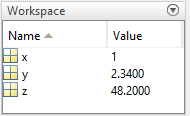

Имена переменных должны удовлетворять следующим условиям:

    ●  Допустимое количество символов в названии: от 1 до 63;

    ●  Имя должно состоять из комбинаций английских малых и больших букв (a-z и A-Z), цифр (0-9), и нижнего подчеркивания (_). 

    ●  Имя должно начинаться с латинской буквы

Примеры представлены в таблице:

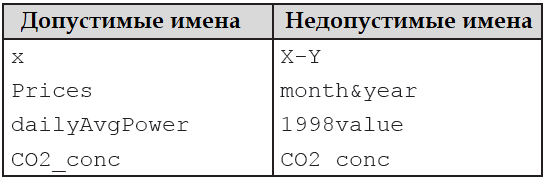

Большие и маленькие латинские буквы различаются интерпретатором MATLAB. Будьте внимательны к регистрам символов! 

Вот пример трех разных переменных: 

spacex = 100

spacex = 100

SPACEX = 20

SPACEX = 20

spaceX = 40

spaceX = 40

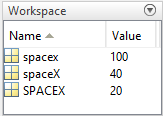

В текст также можно вставлять коментарии с помощью символа "%":

% это комментарий
comm = 31 % и это тоже комментарий

comm = 31

% spaceX = 42; этот код также не будет исполняться

Переменные удаляются следующим образом:

clear comm % удаление одной переменной
clear        % удаление всех переменных  

## Операции над переменными

Базовые арифметические операции:

a = (12 + 3*4)/6

a = 4

b = a^3 + 2

b = 66

b = 2*b/11

b = 12

Основные математические функции:

x = sqrt(25) + log(11) - exp(log10(1324) + log2(1/64)) 

x = 7.3417

y = sin(pi/2)+ cos(x) + tan(1/2)

y = 2.0365

z = atan(x) - asin(0.8)/acos(0.99)

z = -5.1161

log - натуральный логарифм, log10 - десятичный логарифм, log2 - логарифм по основанию 2.

Тригонометрические функции, аргументами которых выступают углы, выраженные в градусах:

x = x + sind(90) - cosd(180) 

x = 9.3417

y = y - tand(45)

y = 1.0365

Также представлены гиперболические функции:

z = sinh(x) + cosh(y) + tanh(z)

z = 5.7022e+03

Бесконечности и отсутствующие/неопределённые значения определяются как `Inf и NaN`:

Strange1 = 5/0

Strange1 = Inf

Strange2 = log(0)

Strange2 = -Inf

Strange3 = Inf - Inf

Strange3 = NaN

Strange4 = NaN 

Strange4 = NaN

## Создание векторов

Векторы в MATLAB могут быть представлены в виде вектора-строки и вектора столбца.

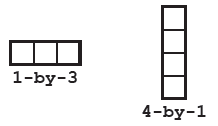

Переменные, рассмотренные ранее, формально, также являются векторами с размерностью 1х1.

Их можно создавать покомпонентно:

vector_13 = [1, 2, 3] % вектор записан в виде строки из чисел через запятые

vector_13 =      1     2     3


vector_13_s = [1 2 3] % вектор записан в виде строки из чисел через пробелы

vector_13_s =      1     2     3


vector_31 = [1; 2; 3] % вектор записан в виде столбца из чисел

vector_31 =      1
     2
     3


Создать вектор с известными начальными и конечными компонентами при известном приращении (шаге) можно так:

`Вектор-строка`` = Первый_элемент``:``Шаг``:``Конечный_элемент` 

c = 3:1:8 

c =      3     4     5     6     7     8


Если вместо шага известно количество компонентов, вектор задается функцией 

`linspace(``Первый_элемент``,`` Конечный_элемент``,`` Количество_элементов``)`

d = linspace(2,3,6)

d =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


Вектор-строку можно превратить в вектор-столбец операцией транспонирования:

c'

ans =      3
     4
     5
     6
     7
     8


d'

ans =     2.0000
    2.2000
    2.4000
    2.6000
    2.8000
    3.0000


**Вектора со случайными** значениями компонентами могут быть созданы с помощью функций `rand``, ``randn``, ``randi``.` 

Аргументом этих функций является размерность. Например, случайной строке длиной `n `соответствует размерность `(1,n)`, а случайному столбцу того же размера `(n,1)`. Вопрос размерностей более углублённо рассмотрен в сл. лекции (1.1.09 "Матричные операции")

Функция `rand()` вызывает равномерное распределение на интервале (0,1):

rand(1,6)

ans =     0.5375    0.9883    0.4330    0.1474    0.6602    0.5868


Функция `randi([i_min, i_max])` вызывает равномерное распределение целых чисел на интервале `[i_min, i_max]` ("randi" - "rand integer"):

randi([2,18],1,6)

ans =     17    16     7     4    13     8


Функция `randn()` вызывает нормальное распределение с мат. ожиданием 0 и среднеквадратичным отклонением 1:

randn(1,6)

ans =     0.3188   -0.3004   -0.8943    0.1219   -0.7497   -1.9854


Операция **конкатенации** (соединения) двух векторов-строк и векторов-столбцов выполняется следующим образом:

conc_str = [vector_13 , d]

conc_str =     1.0000    2.0000    3.0000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


conc_stolb = [c'; vector_31]

conc_stolb =      3
     4
     5
     6
     7
     8
     1
     2
     3


Слова, как наборы символов, могут быть представлены в виде вектора-строки из символов:

char_1 = 'Преступление'

char_1 = 'Преступление'

К ним может быть также применена операция конкатенации:

char_2 = 'наказание';
char_3 = ' и ';
[char_1, char_3, char_2]

ans = 'Преступление и наказание'

Также можно преобразовывать числа в текст с помощью команды `num2str`:

char_num = num2str(d(3))

char_num = '2.4'

[char_2,  ' стоит ', char_num, ' рубля']

ans = 'наказание стоит 2.4 рубля'

## Доступ к компонентам вектора

Все компоненты вектора пронумерованы так (братите внимание, что нумерация вектора начинается с **единицы**):

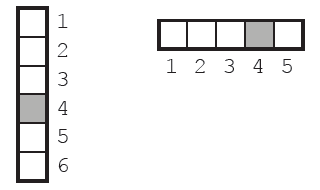

Обращаться к компонентам векторам следует следующим образом:

vector_13(2)

ans = 2

Компоненты вектора переопределяемы:

d(4) = d(3)+d(2)

d =     2.0000    2.2000    2.4000    4.6000    2.8000    3.0000


К последнему компоненту вектора можно обращаться как к номеру **end:**

d(end) 

ans = 3

d(end-1)

ans = 2.8000

Можно также вызывать сразу несколько компонентов вектора по их номерам: 

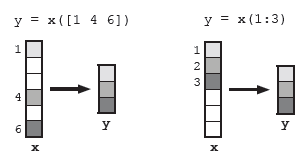

Пример:

d([1 4 3])

ans =     2.0000    4.6000    2.4000


d(3:end-1)

ans =     2.4000    4.6000    2.8000


Можно также заменять сразу несколько компонентов вектора одновременно:

Длина вставляемого элемента должна совпадать с длиной места, куда вставлять!

Можно заменять выбранные компоненты вектора на одно число: 

Удаление компонента вектора производится присвоением пустого компонента:

d_cut = d

d_cut =     2.0000    2.2000    2.4000    4.6000    2.8000    3.0000


d_cut(2) = []

d_cut =     2.0000    2.4000    4.6000    2.8000    3.0000


## Операции над векторами

Векторы **одинаковой длинны** можно складывать, вычитать, а также складывать, вычитать, умножать и делить на числа:

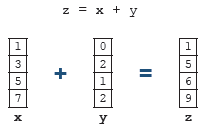                           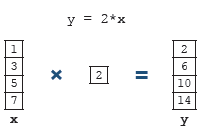

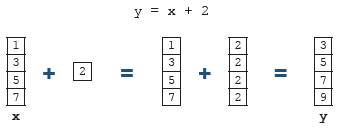

Пример:

e = (-2*c + 5*(d+1))/8

e =     1.1250    1.0000    0.8750    2.0000    0.6250    0.5000


Для покомпонентного умножения двух векторов, а также покомпонентного деления и возведения в степень перед арифметическим символом ставится точка:

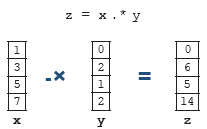

Пример:

f = (c.*d + d./c + c.^2).^e 

f = 	1.0e+03 *

    0.0221    0.0254    0.0238    4.1431    0.0141    0.0094


Ко всем компонентам вектора можно применять математические функции:

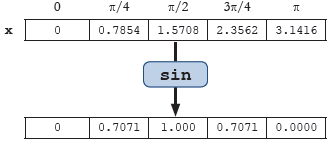

Пример:

g = 0:pi/4:pi;
sin_g = sin(g)

sin_g =          0    0.7071    1.0000    0.7071    0.0000


cos_g = cos(g)

cos_g =     1.0000    0.7071    0.0000   -0.7071   -1.0000


exp_g = exp(g)

exp_g =     1.0000    2.1933    4.8105   10.5507   23.1407


log_g = log(g+1)

log_g =          0    0.5796    0.9442    1.2108    1.4211


## Встроенные функции над векторами

Рассмотрим некоторые встроенные функции над векторами на примере такого вектора:

NL_vect = log(0.5:0.25:3)

NL_vect =    -0.6931   -0.2877         0    0.2231    0.4055    0.5596    0.6931    0.8109    0.9163    1.0116    1.0986


**Длина вектора** (количество компонент) находится с помощью функции `length`: 

length(NL_vect)

ans = 11

также может быть найдено **среднеарифметическое** и **медианное** значение с помощью функций `mean` и `median` соответственно:

mean(NL_vect)

ans = 0.4307

median(NL_vect)

ans = 0.5596

 Значение **максимального и минимального** компонента вектора, а также их номера определяются с помощью функций `min` и `max` соответственно: 

[min_f,min_id] = min(NL_vect)

min_f = -0.6931

min_id = 1

[max_f,max_id] = max(NL_vect)

max_f = 1.0986

max_id = 11

**Норма** порядка p находится с помощью известного выражения:

,

Эта функция реализована как `norm``(X,p):`

norm(NL_vect, Inf)  % p = Inf

ans = 1.0986

norm(NL_vect, 8) 

ans = 1.1899

norm(NL_vect, 2) % Евклидова норма, стоит по умолчанию

ans = 2.3019

norm(NL_vect)

ans = 2.3019

**Сумма** всех компонент вектора:

sum(NL_vect)

ans = 4.7380

**Скалярное произведение** векторов:

dot(d, e)

ans = 19

**Векторное произведение** векторов (операция разрешена если размерность обоих векторов равна 3):

cross(d(1:3), e(1:3))

ans =    -0.4750    0.9500   -0.4750


## Введение в построение графиков

Графики строятся с помощью функции `plot(``x,y``)`. Для корректной работы этой функции ей требуется два вектора одинаковой длины. Абсцисса каждой точки берётся из первого вектора, а ордината - из второго вектора с таким же порядковым номером:

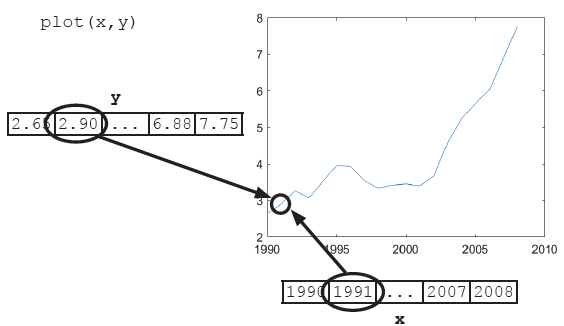

    Для иллюстрации работы функции plot рассмотрим следующий скрипт, отображающий синусоиду на заданном диапазоне:

n = 10:0.1:29.9 % задаётся диапазон

n =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000


m = sin(n) 

m =    -0.5440   -0.6251   -0.6999   -0.7677   -0.8278   -0.8797   -0.9228   -0.9566   -0.9809   -0.9954   -1.0000   -0.9946   -0.9792   -0.9540   -0.9193   -0.8755   -0.8228   -0.7620   -0.6935   -0.6181   -0.5366   -0.4496   -0.3582   -0.2632   -0.1656   -0.0663    0.0336    0.1332    0.2315    0.3275    0.4202    0.5087    0.5921    0.6696    0.7404    0.8038    0.8592    0.9060    0.9437    0.9720    0.9906    0.9993    0.9980    0.9868    0.9657    0.9349    0.8948    0.8457    0.7883    0.7229


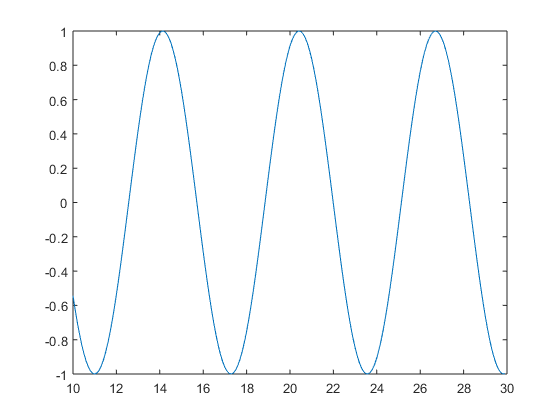

plot(n,m)  

Если не вводить вектор абсцисс (в приведённом примере - вектор *n*), то по оси абсцисс будет откладываться порядковые номера компонентов вектора:

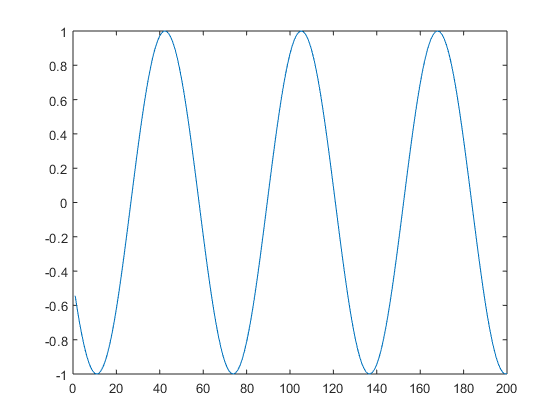

plot(m)

    Для добавления кривых на график используется команда `hold on`**:**

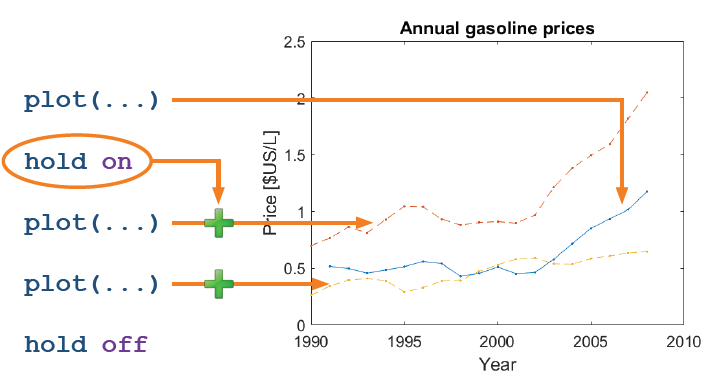

    Пример скрипта для построения нескольких кривых приведен ниже:

k = 0.2*log(n-3)    % формирование вектора для 2-й кривой

k =     0.3892    0.3920    0.3948    0.3976    0.4003    0.4030    0.4056    0.4082    0.4108    0.4134    0.4159    0.4184    0.4208    0.4233    0.4256    0.4280    0.4304    0.4327    0.4350    0.4372    0.4394    0.4417    0.4438    0.4460    0.4481    0.4503    0.4524    0.4544    0.4565    0.4585    0.4605    0.4625    0.4645    0.4664    0.4684    0.4703    0.4722    0.4740    0.4759    0.4778    0.4796    0.4814    0.4832    0.4850    0.4867    0.4885    0.4902    0.4919    0.4936    0.4953


l = 0.5 * cos(n)    % формирование вектора для 3-й кривой

l =    -0.4195   -0.3903   -0.3571   -0.3204   -0.2805   -0.2378   -0.1927   -0.1456   -0.0972   -0.0477    0.0022    0.0521    0.1015    0.1499    0.1967    0.2417    0.2841    0.3238    0.3602    0.3930    0.4219    0.4466    0.4668    0.4824    0.4931    0.4989    0.4997    0.4955    0.4864    0.4724    0.4537    0.4305    0.4029    0.3714    0.3361    0.2975    0.2559    0.2117    0.1654    0.1175    0.0684    0.0186   -0.0314   -0.0811   -0.1299   -0.1775   -0.2232   -0.2668   -0.3077   -0.3455


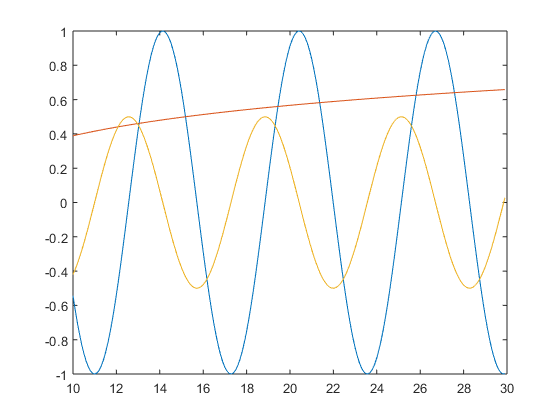

plot(n,m)       % отрисовка 1-й кривой
hold on
plot(n,k)       % отрисовка 2-1 кривой
plot(n,l)       % отрисовка 3-й кривой
hold off       

## Введение в оформление графиков

    С помощью функции `plot` можно рисовать не только линии. Рассмотрим, как отображать каждую точку желаемым маркером, как управлять цветом и стилем кривых. Более детально вопрос оформления графиков будет рассмотрен в лекции №1.2.07.

    В функцию `plot` можно добавлять свойства:

    Перечень этих свойств представлен в таблице:

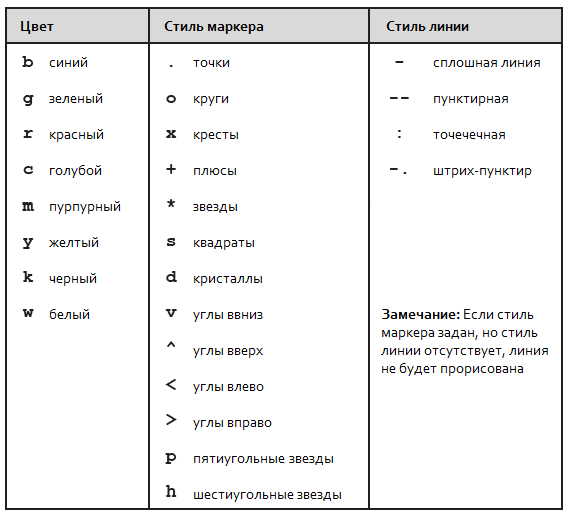

Пример использования свойств из приведённой таблицы : 

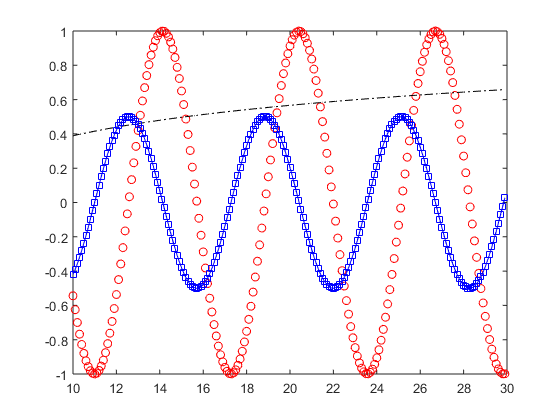

plot(n,m, 'ro')       % красные круги
hold on
plot(n,k, 'k-.')       % черная штрих-пунктирная линия
plot(n,l, 'sb-')       % синие квадраты и сплошная линия
hold off    

Подписи осей, и вставка названия реализуются с помощью функций `title`, `xlabel `и `ylabel`. В названия можно вставлять греческие буквы в стиле TeX (например `'\gamma' '\pi' '\omega'`):

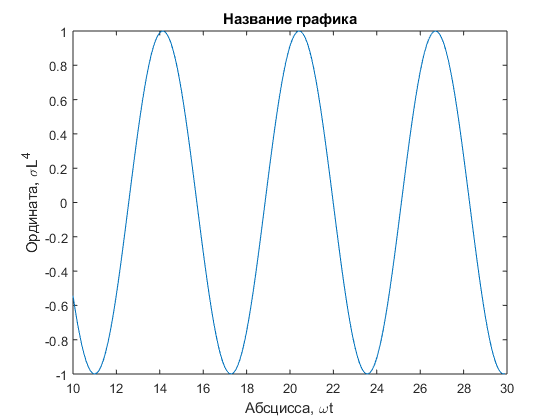

plot(n,m)       % отрисовка кривой
title('Название графика')
xlabel('Абсцисса, \omegat')
ylabel('Ордината, \sigmaL^4')

Кривые можно подписать с помощью команды `legend`:

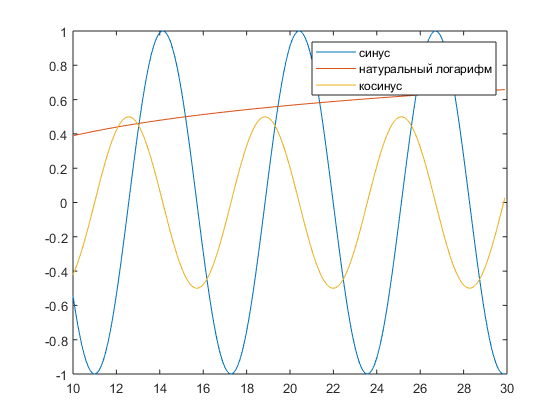

plot(n,m)       % отрисовка синуса
hold on
plot(n,k)       % отрисовка натурального логарифма
plot(n,l)       % отрисовка косинуса
hold off     

legend('синус', 'натуральный логарифм', 'косинус')